# OptMeths_ex5

## Exercise 1

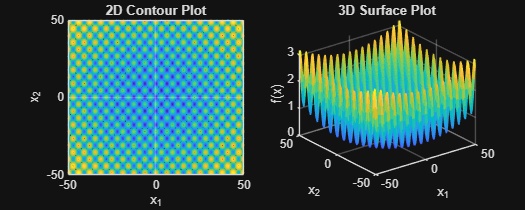

griewank = @(x) (x(1)^2 + x(2)^2)/4000 - cos(x(1)/sqrt(1))*cos(x(2)/sqrt(2)) + 1;

[X1, X2] = meshgrid(-50:0.5:50, -50:0.5:50);
Z = arrayfun(@(x, y) griewank([x, y]), X1, X2);

figure('Name', 'Griewank Function', 'Position', [100, 100, 1000, 400]);
subplot(1, 2, 1);
contour(X1, X2, Z, 20);
title('2D Contour Plot'); xlabel('x_1'); ylabel('x_2'); grid on;

subplot(1, 2, 2);
mesh(X1, X2, Z);
title('3D Surface Plot'); xlabel('x_1'); ylabel('x_2'); zlabel('f(x)');

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


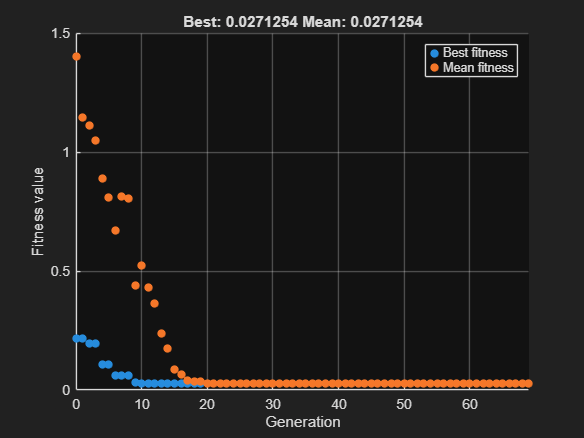


options = gaoptimset('PlotFcns', {@gaplotbestf});
lb = [-50, -50]; 
ub = [50, 50];
[x_opt, fval_opt] = ga(griewank, 2, [], [], [], [], lb, ub, [], options);


fprintf('Griewank function\n');

Griewank function


fprintf('Optimal point: [%.6f, %.6f]\n', x_opt(1), x_opt(2));

Optimal point: [-9.420063, -4.438445]


fprintf('Val. of func.: %.6e\n\n', fval_opt);

Val. of func.: 2.712538e-02



## Exercise 2

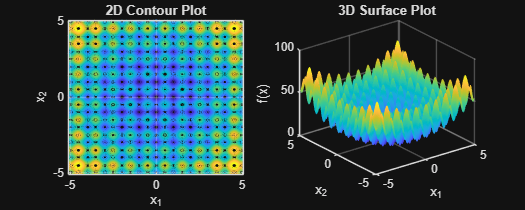

rastrigin = @(x) (x(1)^2 - 10*cos(2*pi*x(1)) + 10) + (x(2)^2 - 10*cos(2*pi*x(2)) + 10);

[X1, X2] = meshgrid(-5.12:0.05:5.12, -5.12:0.05:5.12);
Z = arrayfun(@(x, y) rastrigin([x, y]), X1, X2);

figure('Name', 'Rastrigin Function', 'Position', [100, 100, 1000, 400]);
subplot(1, 2, 1);
contour(X1, X2, Z, 20);
title('2D Contour Plot'); xlabel('x_1'); ylabel('x_2'); grid on;

subplot(1, 2, 2);
surf(X1, X2, Z, 'EdgeColor', 'none');
title('3D Surface Plot'); xlabel('x_1'); ylabel('x_2'); zlabel('f(x)');

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


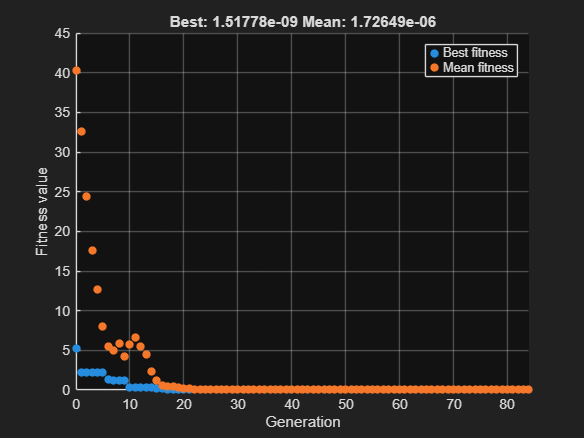


options = gaoptimset('PlotFcns', {@gaplotbestf});
lb = [-5.12, -5.12]; 
ub = [5.12, 5.12];
[x_opt, fval_opt] = ga(rastrigin, 2, [], [], [], [], lb, ub, [], options);


fprintf('Optimal point: [%.6f, %.6f]\n', x_opt(1), x_opt(2));

Optimal point: [0.000003, -0.000001]


fprintf('Func val: %.6e\n\n', fval_opt);

Func val: 1.517778e-09



## Exercise 3

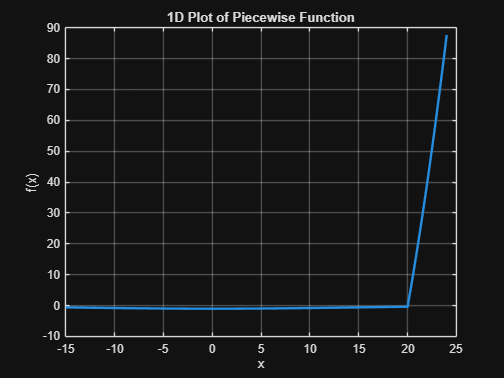

custom_func = @(x) (x <= 20) * (-exp(-(x/20)^2)) + ...
    (x > 20) * (-exp(-1) + (x - 20)*(x - 2));

x_domain = -15:0.1:24;
y_values = arrayfun(custom_func, x_domain);

figure('Name', 'Piecewise Function');
plot(x_domain, y_values, 'LineWidth', 2);
title('1D Plot of Piecewise Function'); xlabel('x'); ylabel('f(x)'); grid on;

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


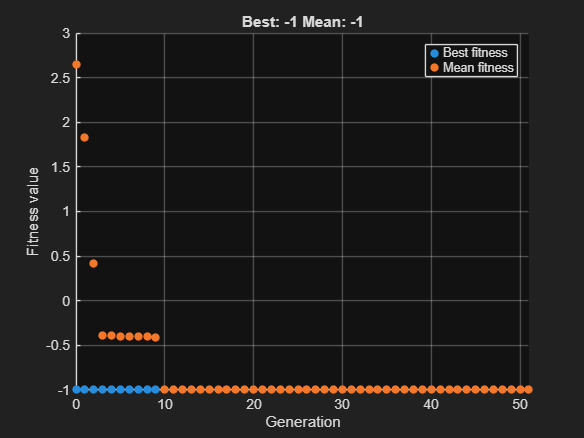


options = gaoptimset('PlotFcns', {@gaplotbestf});
lb = -15; 
ub = 24;
[x_opt, fval_opt] = ga(custom_func, 1, [], [], [], [], lb, ub, [], options);


fprintf('Optimal point: %.6f\n', x_opt);

Optimal point: 0.000007


fprintf('Func val: %.6f\n', fval_opt);

Func val: -1.000000
